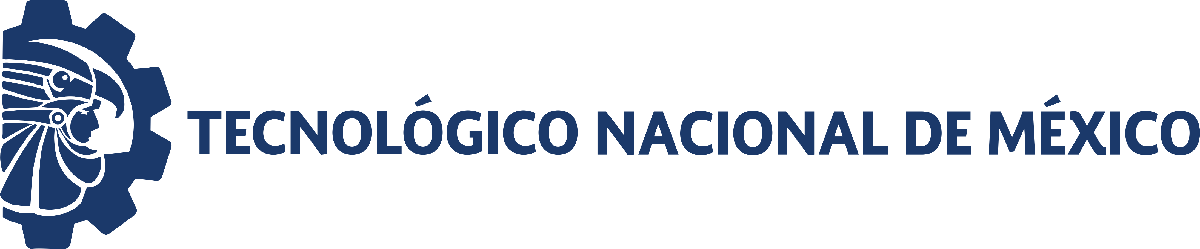                                 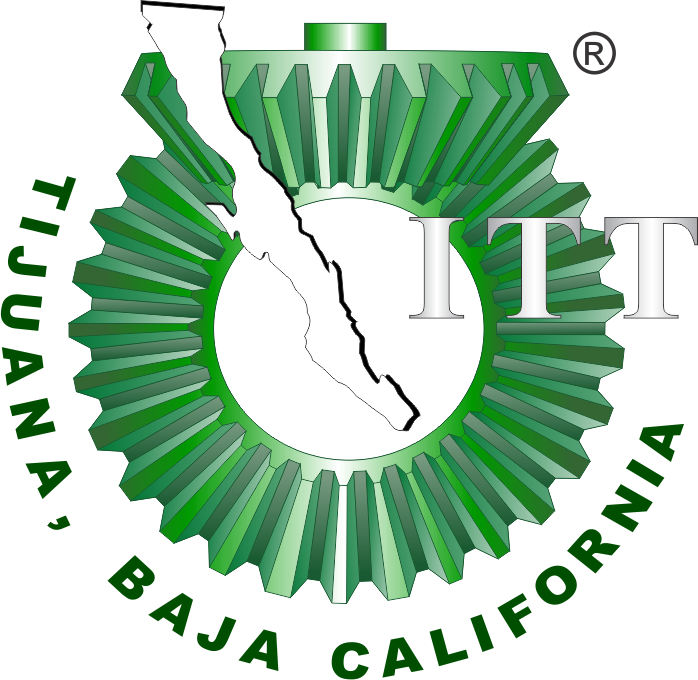

# Práctica uno: Diseño de controlador para un sistema de 2do orden

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[Foto]

Nombre del alumno: Jeanette Cubillas Arteaga 

Número de control: 20212948

Correo institucional: l20212948@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SistemaP1';
open_system(file);
parameters.Stoptime = tend;
parameters.Solver = 'ode45';
parameters.MaxStep = '1E-3';
Controlador = 'I';

## Respuesta al escalón

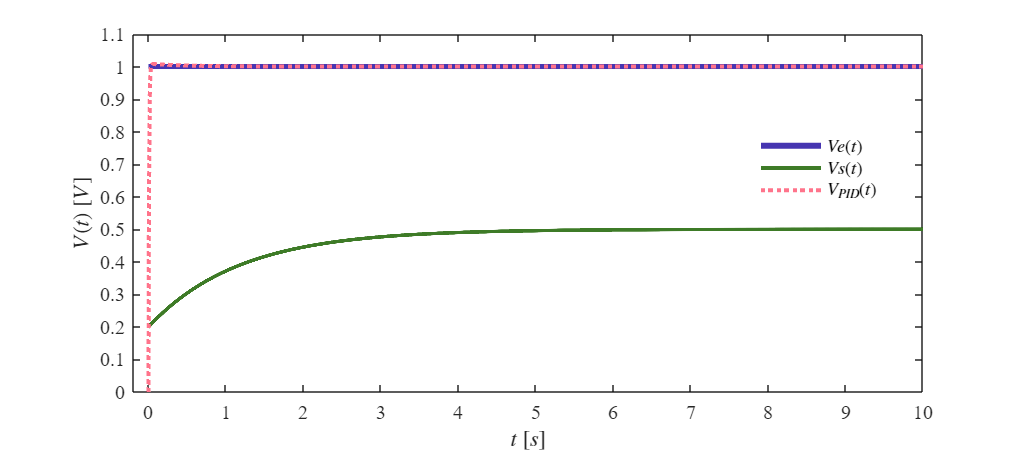

Signal = 'Escalon';
set_param('SistemaP1/S1','sw','1')
set_param('SistemaP1/Ve(t)','sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Ve,x1.Vs,x1.PID,Signal)

## Respuesta al impulso

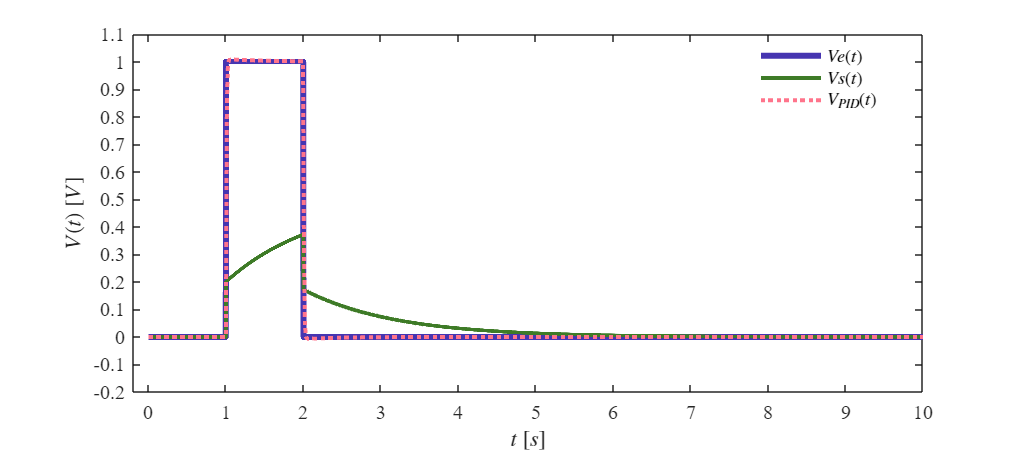

Signal = 'Impulso';
set_param('SistemaP1/S1','sw','0')
set_param('SistemaP1/Ve(t)','sw','1');
x2 = sim(file,parameters);
plotsignals(x2.t,x2.Ve,x2.Vs,x2.PID,Signal)

## Respuesta a la rampa

Signal = 'Rampa'

Signal = 'Rampa'

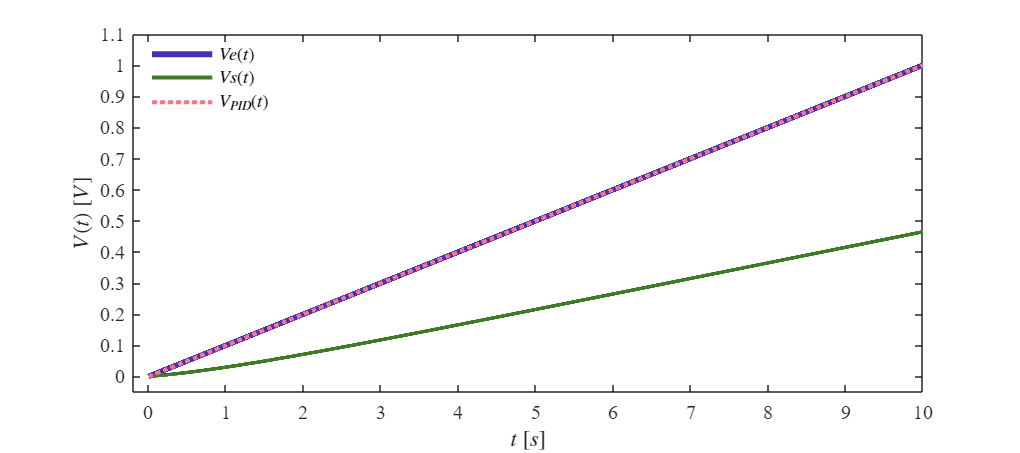

set_param('SistemaP1/S2','sw','1');
set_param('SistemaP1/Ve(t)','sw','0');
x3 = sim(file,parameters);
plotsignals(x3.t,x3.Ve,x3.Vs,x3.PID,Signal)

## Respuesta a la función sinusoidal

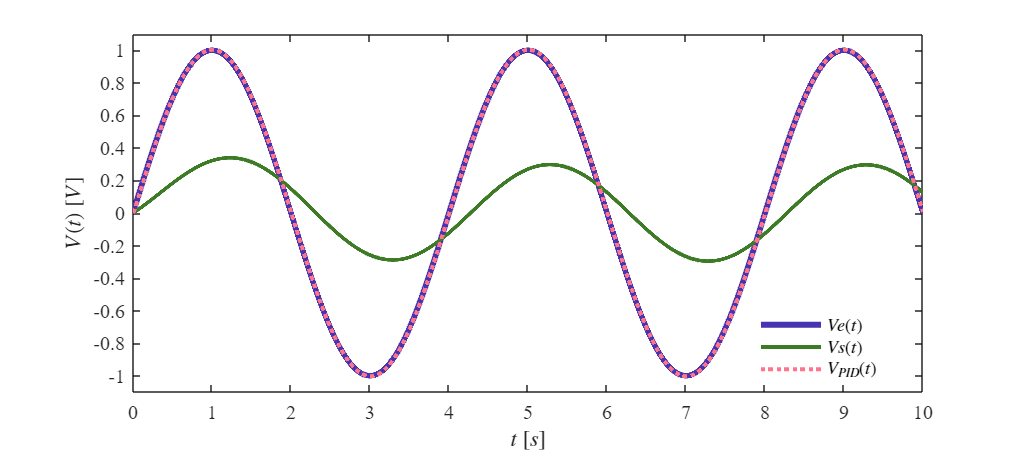

Signal = 'Sinusoidal';
set_param('SistemaP1/S2','sw','0')
set_param('SistemaP1/Ve(t)','sw','0');
x4 = sim(file,parameters);
plotsignals(x4.t,x4.Ve,x4.Vs,x4.PID,Signal)

## Función: Respuesta a las señales 

function plotsignals(t,Ve,Vs,VPID,Signal)
 set(figure(),'Color','w')
 set(gcf,'Units','Centimeters','Position',[1,1,18,8])
 set(gca,'FontName','Times New Roman')
 fontsize(10,'points')
 Morado = [70/255,53/255,177/255];
 Verde =  [62/255,123/255,39/255];
 Rosa = [255/255, 116/255, 139/255];
 hold on; grid off; box on 

 plot(t,Ve,'LineWidth',3,'Color',Morado)
 plot(t,Vs,'LineWidth',2,'Color',Verde)
 plot(t,VPID,':','LineWidth',2,'Color',Rosa)

 xlabel('$t$ $[s]$','Interpreter','Latex')
 ylabel('$V(t)$ $[V]$','Interpreter','Latex')
 L= legend('$Ve(t)$','$Vs(t)$','$V_{PID}(t)$');
 set(L,'Interpreter','Latex','Location','Best','Box','Off')

 if Signal == "Escalon"
     xlim([-0.2,10]); xticks(0:1:10)
     ylim([0,1.1]); yticks(0:0.1:1.1)
 elseif Signal == "Impulso"
     xlim([-0.2,10]); xticks(0:1:10)
     ylim([-0.2,1.1]); yticks(-0.2:0.1:1.1)
 elseif Signal == "Rampa"
     xlim([-0.2,10]); xticks(0:1:10)
     ylim([-0.05,1.1]); yticks(0:0.1:1.1)
 elseif Signal == "Sinusoidal"
     xlim([0,10]); xticks(0:1:10)
     ylim([-1.1,1.1]); yticks(-1.2:0.2:1.2)
 end
 exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
end
